## Module 1: Complex Systems and Networks

### Part I: Complex Systems Quantitative Analysis

**Question 1**: Load the data into MATLAB. Look only at the last 504 days of trading prices. Divide each ticker’s price by its initial opening price 504 days ago so that they all start at 1. Plot these corrected prices against time (for the past two years) for all tickers. Plot, in a 22 x 22 plot array, all the corrected prices against one another. Provide the code you used and the respective images in an image format of your choice. Briefly describe 5 things you see.

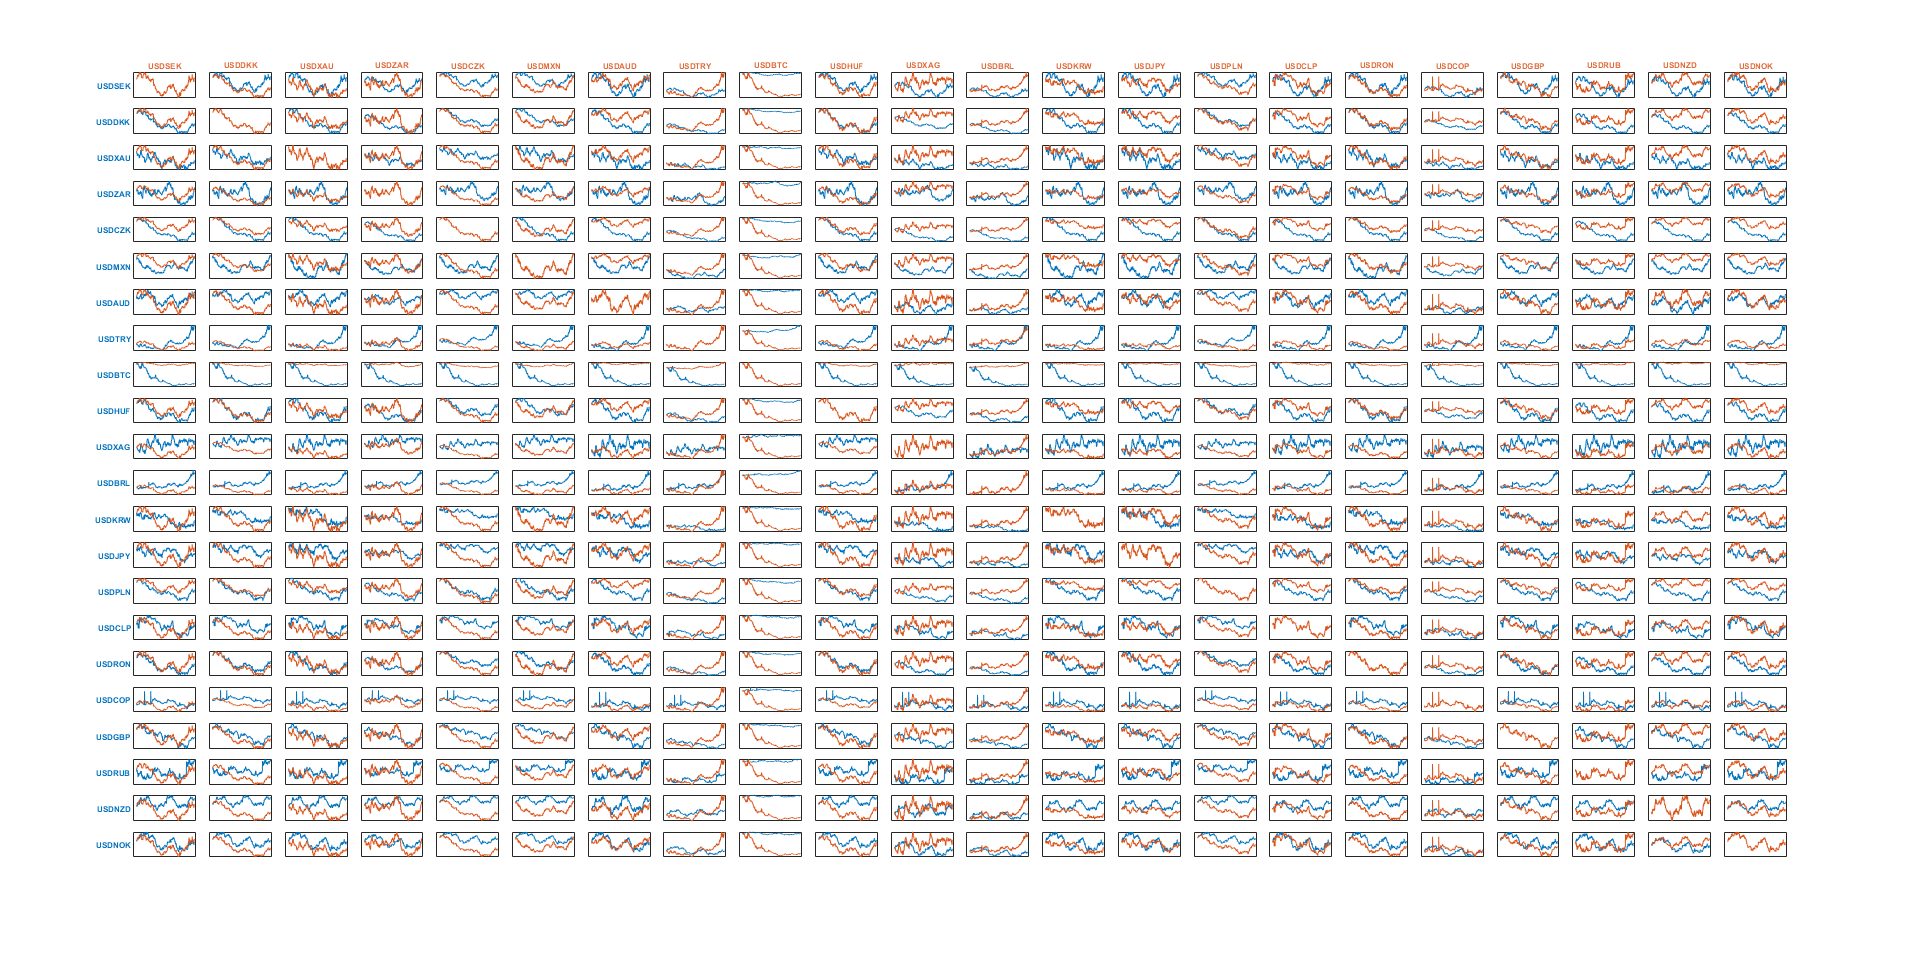

ans =   Figure (1: Figure) with properties:

      Number: 1
        Name: 'Figure'
       Color: [1 1 1]
    Position: [1 41 1920 963]
       Units: 'pixels'

  Show all properties


% Load the data
load("fx-19jun.mat");
day = 504; % Number of days to look at
total_day = size(data, 1); % Total days of data
n_tickers = size(data, 3); % Total numbers of tickers
mt_tickers = 22; % Number of most traded tickers

% Get the data for 504 days of trading price
data = data(total_day-(day - 1):total_day,:, :);
times = times(total_day-(day -1):total_day, :);

% Find 22 most traded tickers among 37 tickers
changes = zeros(1,n_tickers);
for n=1:n_tickers
   data(:,:,n) = data(:, :, n) / data(1,:,n);  
   changes(n) = change(data(:,:, n));   
end

% Remove unwanted tickers based on threshold
threshold = min(maxk(changes, mt_tickers));
index_to_remove = zeros(1, n_tickers - mt_tickers);

i  = 0;
for n = 1:n_tickers
    if change(data(:,:, n)) < threshold
        i = i + 1;
        index_to_remove(i) = n;
    end
end

data(:,:, index_to_remove) = [];
tickers(index_to_remove,:) = [];

% Format the data
data = squeeze(data);
data_table = array2table(data);

for i = 1:22
    data_table.Properties.VariableNames{i} = tickers(i,:);
end

day_column = 'Day';
data_table.(day_column) = times;
writetable(data_table,'myData.csv','Delimiter',',');
times_1 = datetime(times, 'InputFormat','yyyyMMdd');

% Plot 22 x 22 the corrected prices against one another

% e = 22;
% tiledlayout(e,e)
% for i=1:e
%     for j = 1:e
%         a  = nexttile;
%         plot(times_1(:), data(:, i))
%         hold on;
%         plot(times_1(:), data(:, j))
%         set(gca,'xtick',[]);
%         set(gca,'ytick',[]);  
%         if i == 1
%             title(a, tickers(j,:), 'fontweight','bold','fontsize',6, 'color', '#de6836');
%         end
%         
%         if j == 1
%             ylabel(a, tickers(i,:), 'fontweight','bold','fontsize',6, 'color', '#0071bd');            
%             set(get(gca,'ylabel'),'rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle')
%         end        
%         hold off;
%     end
% end

% open the saved plot to save computing time
% open in Matlab to see the best resolution figure
openfig('fx_prices.fig','visible')

A brief description of the plot:

- The trend of USDBTC is greatly different from other tickers.

- A similar pattern can be seen between some pairs of tickers such as USDHUF vs USDDKKK, USDHUF vs USDXAU, ...

- Two peaks shown in plots for USDCOP are noticeable.

- The diagonal of the plot are the prices of tickers against themselves, therefore, the line containing only 1s is displayed.

- When comparing with USDBTC, the changes in the price of other tickers are insignificant.

**Question 2**: Using your corrected prices over the past two years of data, compute the corrected daily returns (i.e. the % daily change in the value) of each ticker. Using this, compute the correlation matrix of daily returns. Check in MATLAB whether the matrix is symmetric and provide evidence whether it is or not. Visualise the correlations matrix appropriately. What is the determinant of this matrix? In 10 words or less, give a geometric interpretation of the determinant of a matrix (5 marks).

daily_returns = zeros(503, 22); % Initialization

% Compute the daily returns
for j =1:22
    for i=1:503
        daily_returns(i,j) = (data(i+1,j) - data(i,j)) / data(i,j);
    end
end

% Compute the correlation matrix of daily returns
correlation = corrcoef(daily_returns);

The correlation matrix is symmetric. It is validated because the "issymmetric()" function returns 1.

is_symmetric = issymmetric(correlation)

is_symmetric = logical
   1


The plot of the correlation matrix:

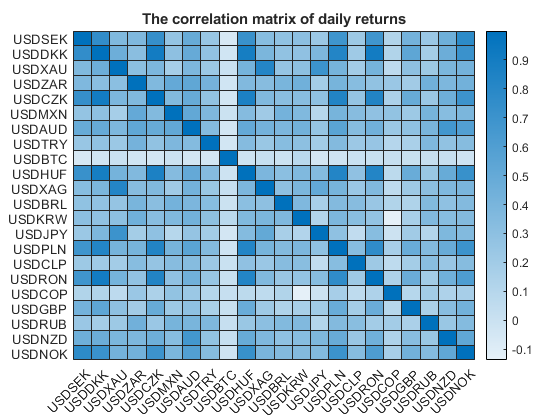

figure;
h = heatmap(correlation);
h.XDisplayLabels = string(tickers);
h.YDisplayLabels = string(tickers);
title("The correlation matrix of daily returns");

The determinant of the correlation matrix is 0. The matrix considered as a transformation takes the basis vectors into vectors that are linearly dependent and define 0 volume.

determinant = round(det(correlation),2)

determinant = 0

**Question 3**: The Marcenko-Pastur distribution describes asymptotic behaviour of the eigenvalues of random matrices. Plot this distribution as a family of curves for different parameter values, N and T, respectively, where N is the number of series and T is their length. Give expressions for the two points along the x-axis at which the MP distribution curves departs from the horizontal axis (i.e. where the MP distribution is > 0), as functions of N and T. What is the significance of any of the eigenvalues of a given non-random matrix derived from time series data falling between these two values? What about those falling outside the range? (5 marks).

The Marcenko-Pastur distribution reads as in the equation below ( Thales, 2020):

    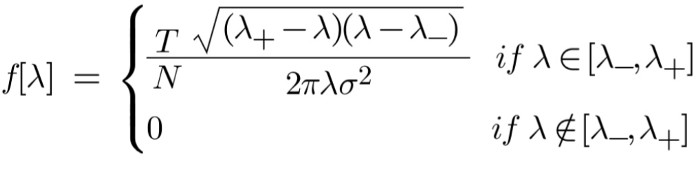

where:

Lamda+ and lamda- are two points along the x-axis at which the MP distribution curves depart from the horizontal axis. For the normal distribution random matrix, the standard deviation equals 1. Any of the eigenvalues of a given non-random matrix that are not failing between these two points would be considered as significant. It means the probability of that eigenvalues attributed to noise is approximately zero. Otherwise, those falling inside the range would be attributed to noise. We could use significant eigenvalues to reconstruct the matrix with noise reduction.

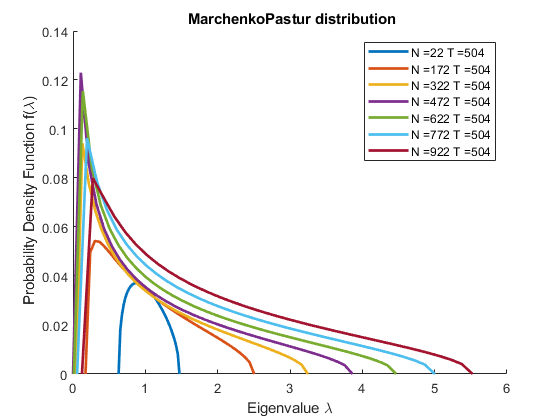

N_set = 22:150:day*2;
legend_labels = [];
figure;
xlabel('Eigenvalue \lambda');
ylabel(' Probability Density Function f(\lambda)');
title(' MarchenkoPastur distribution');
for i = 1:length(N_set)
    N=N_set(i);
    T=504;
    % Ratio of matrix dimensions
    c=N/T;
    
    % Sample
    x=randn(N,T); % Normal distribution
    s=std(x(:)); % s = 1 if normal distribution
    
    % spectral matrix
    r=x*x'/T;
    
    %eigenvalues
    l=eig(r);
    
    % Probability Density Function 
    % Boundaries 
    % Lamda-
    a=(s^2)*(1-sqrt(c))^2;
    % Lamda+
    b=(s^2)*(1+sqrt(c))^2;
    
    [f,lambda]=hist(l,linspace(a,b,n));
    
    % Normalization
    f=f/sum(f);
    
    % Theoretical pdf
    ft=@(lambda,a,b,c) (1./(2*pi*lambda*c*s^(2))).*sqrt((b-lambda).*(lambda-a));
    F=ft(lambda,a,b,c);
    
    % Processing numerical pdf
    F=F/sum(F);
    F(isnan(F))=0;
    
    % Results    
    hold on;
    plot(lambda,F,'LineWidth',2,'DisplayName', strcat('N = ', string(N), 'T = ', string(T)));
    legend_labels = [legend_labels strcat('N = ', string(N), ' T = ', string(T))];
end
legend(legend_labels)
hold off;

**Question 4**: Study the network derived from the correlation matrix you just computed. Is it a directed or undirected matrix? Plot a histogram of its eigenvalues and comment on it (100 words). Plot the distribution of the node degrees and comment on it (100 words). What is the mean correlation between any two randomly chosen ticker price returns in the past year? What is the distribution of the correlations between any two randomly chosen ticker price returns in that time? What is the standard deviation? Comment on the above in 250 words or less (5 marks).

The number of eigenvalues exactly equals the number of dimensions of the correlation matrix. Since it is the correlation matrix for 22 tickers' corrected prices, the dimension is 22. Therefore, we have 22 eigenvalues for the correlation matrix. Looking at the plot for the distribution of eigenvalues, we can see that there are great number of small eigenvalues ranging from 0 to 1.2. There are only 3 large eigenvalues: 1.68, 2.21 and 8.77. The eigenvector which is corresponding with the highest eigenvalue 8.77 is considered as the principal component. Using the significant eigenvectors, we can reduce the dimension of dataset to simplify the data, keep only significant information and make the visualization easier.

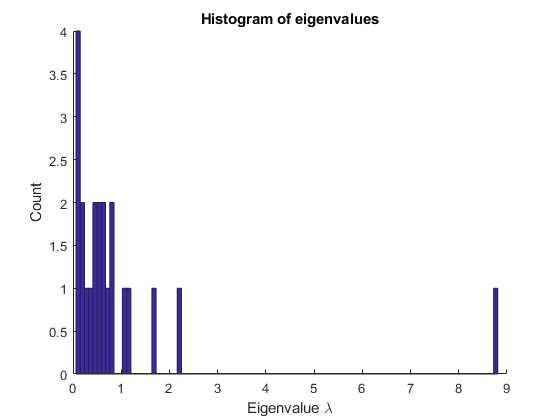

% Plot the Histogram of eigenvalues
[V, D] = eig(correlation);
eig_values = diag(D);
figure;
hold on;
title("Histogram of eigenvalues");
xlabel('Eigenvalue \lambda');
ylabel('Count');
hist(eig_values, 100);
hold off;

The correlation matrix is used to construc the undirected network. The nodes of the networks are the tickers. Two nodes are connected to each other if they are correlated. Since the network indicates the correlation of 22 tickers against each other, it is clear that one node connects to 21 other nodes (a node does not points to itself). Therefore, the network include 22 nodes and each node has the degree of 21.

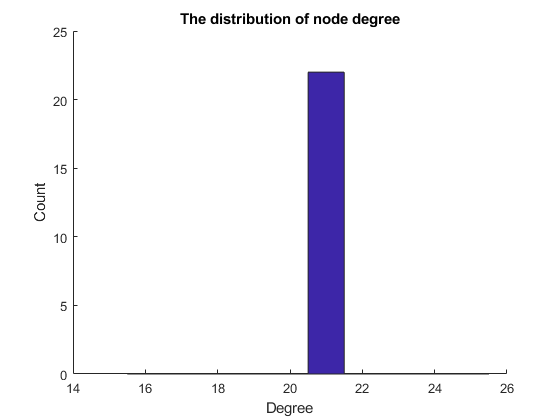

% Plot the distribution of degree
% Construct the undirected network and a node would not point to itself
correlation(correlation == 1) = 0;
labels2 = string(tickers);
G = graph(correlation, labels2);
D = degree(G);

figure;
hold on;
title("The distribution of node degree");
xlabel("Degree");
ylabel("Count");
hist(D, 10);
hold off;

Looking at the distribution plot, it is clear that there are a major peak ( for the weight values 0.3 - 0.4) and one minor peak (0.7 - 0.9)  can be witnessed. It means that there are many nodes which are barely and weakly correlated to each other. However, a significant number of nodes do still have strong correlation. That strong correlated node group would be in our interest to analyse for the future question.

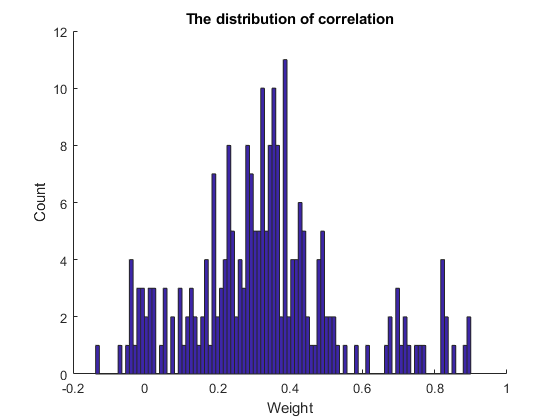

% Plot the distribution of correlation
figure;
hold on;
title("The distribution of correlation");
xlabel("Weight");
ylabel("Count");
temp = tril(correlation);
temp = temp(temp ~= 0);
hist(temp, 100)
hold off;

The mean correlation between any two randomly chosen ticker price returns in the past years is:

mean_correlation = round(mean(temp(:)), 2)

mean_correlation = 0.3300

The standard deviation is:

std_correlation = round(std(temp(:)), 2)

std_correlation = 0.2100

The mean of the correlation is calculated by adding all correlations and then dividing by the numbers of correlationsin the matrix. It is used to measure the central tendency. It shows the average value of a distribution of figures. The standard deviation (SD) is mainly used to measure the variability. It indicates how much the variation is between the data and the average (mean). The calculated SD of the correlation matrix is 0.2, which is pretty low. Therefore, we may conclude that the data points tend to be close to the mean. It is true because we can see from the distribution plot that there are great number of correlations that have value ranging from 0.1 to 0.5.

One SD away from the mean is expected to include around 68 percentage of the number of data. It means 68% of the number of correlations have value between 0.12 to 0.54. Two SDs away from the mean account for about 95 percentage of the number of data. Then, we can estimate that 95% of the number of correlations have value between -0.11 to 0.75. And three SDs account for about 99 percent of the data.

**Question 5:** Your evil employer’s investment strategy focusses around choosing currencies that  its analysts believe are geographic regions (Asia, Europe, etc) that are “on the rise”  and avoiding those that are “falling” relative to the USD. Naturally, having taken  MXB361, you are sceptical of such an approach absent evidence in its favour. You  decide to use community detection methods to see if there are any distinct  communities in the ticker returns over the last year and if so, if they overlap with  the GICS sectors. Your first step is to write your own community detection code.  Choose an algorithm you’ve come across (such as Potts, Louvain, etc.) or devise  your own and write a piece of code in MATLAB that takes as input an adjacency  matrix (for example, a correlation matrix) and maximises the modularity, outputting  the communities within the network and a value for the estimated maximum  modularity. Provide evidence that the method works on a small network you have  devised (5 marks)

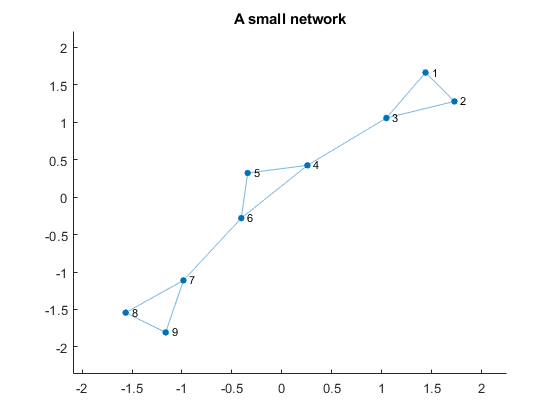

% A small network to test
A = [ 0 1 1 0 0 0 0 0 0;
      1 0 1 0 0 0 0 0 0;
      1 1 0 1 0 0 0 0 0;
      0 0 1 0 1 1 0 0 0;
      0 0 0 1 0 1 0 0 0;
      0 0 0 1 1 0 1 0 0;
      0 0 0 0 0 1 0 1 1;
      0 0 0 0 0 0 1 0 1;
      0 0 0 0 0 0 1 1 0;];
figure;
hold on;
title("A small network")
plot(graph(A));
hold off;



% Community detection maximize modularity
%
% Reference: Newman, Mark EJ. "Fast algorithm for detecting community structure in 
% networks." Physical review E 69.6 (2004): 066133. 
%
% INPUT
% A:      Adjacency matrix of graph
%
% OUTPUT
% com:     N-ny-1 matrix, com(n) is the community to which node n belongs
% Q: the estimated maximum modularity


% Set initial communities with one node per community
current_com = (1:length(A))';

% Initialise best community to current value
com = current_com;

% Compute initial community matrix
e = get_community_matrix(A,com);

% Lines and columns sum (speed optimisation)
ls = sum(e,2);
cs = sum(e,1);

% Initialise best known and current Q values
current_Q = trace(e) - sum(sum(e^2));
Q = current_Q;

% Loop until no more aggregation is possible
while length(e) > 1
    % Best Q variation
    loop_best_dQ = -inf;
    % For all the pairs of nodes that could be merged
    can_merge = false;
    for i=1:length(e)
        for j=i+1:length(e)
            % If they share edges
            if e(i,j) > 0
                % Compute the variation in Q
                dQ = 2 * (e(i,j) - ls(i)*cs(j));
                % If best variation, then keep track of the pair
                if dQ > loop_best_dQ
                    loop_best_dQ = dQ;
                    best_pair = [i,j];
                    can_merge = true;
                end
            end
        end
    end
    if ~can_merge
        disp('!!! Graph with isolated communities, no more merging possible !!!');
        break;
    end
    
    % Merge the pair of clusters maximising Q
    best_pair = sort(best_pair);
    for i=1:length(current_com)
        if current_com(i) == best_pair(2)
            current_com(i) = best_pair(1);
        elseif current_com(i) > best_pair(2)
            current_com(i) = current_com(i) - 1;
        end    
    end
    
    % Update community matrix
    e(best_pair(1),:) = e(best_pair(1),:) + e(best_pair(2),:);
    e(:,best_pair(1)) = e(:,best_pair(1)) + e(:,best_pair(2));
    e(best_pair(2),:) = [];
    e(:,best_pair(2)) = [];
    
    % Update lines/colums sum
    ls(best_pair(1)) = ls(best_pair(1)) + ls(best_pair(2));
    cs(best_pair(1)) = cs(best_pair(1)) + cs(best_pair(2));
    ls(best_pair(2)) = [];
    cs(best_pair(2)) = [];
    
    % Update Q value
    current_Q = current_Q + loop_best_dQ;
    
    % If new Q is better, save current partition
    if current_Q > Q
        Q = current_Q;
        com = current_com;
    end
end


Test result with a small graph

community = com

community =      1
     1
     1
     2
     2
     2
     3
     3
     3


modularity = round(Q, 2)

modularity = 0.4800

The algorithms sucessfully determine the community with in the test network. The result indicates that node 1, 2 and 3 belong to same group, node 4, 5 and 6 belong to same group, and node 7, 8, and 9 belong to same group.

**Question 6:** In order to feed a noise-cleaned network into your community detection code, you  need to eliminate some eigenvectors from the correlations matrix you computed.  Based on you answer to Q5 above, set the eigenvalues that you think are  indistinguishable from noise to 0 and reconstitute the matrix using only the non-noise eigenvalues/vectors. Study the degree distribution of this new matrix/network. How, if at all, is it different from your answer in Q5? What  proportion of the eigenvalues were eliminated in this way? What does this  proportion tell you about the level of noise in the initial correlation matrix? How  would this all change if the values of T and N changes? In particular, for what  combination(s) of T and N is the correlation matrix indistinguishable from a random  matrix, and justify the reason for this claim using the expressions you reported in  your answer from Q3 (5 marks).

% Identify the range
lamda = mt_tickers/day;
lamda_plus = (1+sqrt(lamda))^2;
lamda_minus = (1-sqrt(lamda))^2;

%Calculate eigevalue/vectors for the correlation data
correlation(1:1+size(correlation,1):end) = 1;
[V1, D1] = eig(correlation);
D1_abs = abs(D1);

% Set the eigenvalues that are  indistinguishable from noise to 0
D1_filter = (D1_abs >= lamda_plus); 
D1_reconstitued = D1 .* D1_filter;

%  A*V = V*D.
correlation_reconstituted = V1 * D1_reconstitued * inv(V1);
correlation_reconstituted = abs(correlation_reconstituted);

The figure below show the distribution of correlation of newly reconstituted matrix:

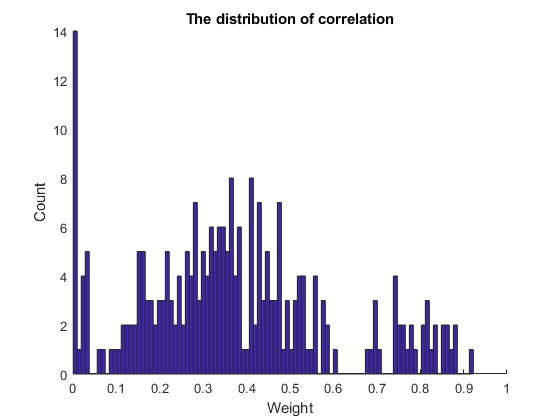

% Plot the distribution of correlation
figure;
hold on;
title("The distribution of correlation");
xlabel("Weight");
ylabel("Count");
temp = tril(correlation_reconstituted);
temp = temp(temp ~= 0);
hist(temp, 100)
hold off;

The mean is:

mean_correlation = round(mean(temp(:)), 2)

mean_correlation = 0.3700

The standard deviation is:

std_correlation = round(std(temp(:)), 2)

std_correlation = 0.2200

We can see that there is no significant change in the mean and the standard deviation of the new correlation matrix. However, the new distribution plot shows things more clear. Now, the highest peak is seen at the edges with a value from 0 - 0.05. It means after implementing the noise reduction method, many edges are considered insignificant. There are three distribution groups: 0 - 0.1, 0.1 - 0.6 and 0.7 - 0.9. Based on that, we can set the threshold to study different aspects of the network. The noise reduction method removes the eigenvalues that are in the range of 'lamda_minus' and 'lamda_minus'. It only keeps the 3 highest out of 22 values. Therefore, the percentage of eliminated values is around 86.36% - which implies the rate of noise in the initial correlation matrix was considerably high. That percentage would change based on the values of N/T  because of the expression shown before. It shows that the higher value of N/T is, the greater the range between 'lamda_minus' and 'lamda_plus' is. When N = T, the correlation matrix is indistinguishable from a random matrix. When N/T = 1, we have the values of 'lamda_minus' and 'lamda_plus' are 0 and 4 respectively. 

**Question 7: **Apply your community detection code to the new, noise-cleaned matrix in order to find modules in your data. Are there any and if so, how many? What is the modularity maximum your code found? Plot on a world map bubbles/dots corresponding to each currency placed over the geographic coordinates of each country’s capital city (for bitcoin, gold and silver, just place the dots somewhere “empty” to the side, e.g. over the Pacific). Provide the image and code. Does the membership of these modules overlap with the geographic regions? If not, how big is the difference? Do their “locations” make any sense, with respect to their economic activity (you may need to do a bit of research on that latter aspect)? Where  do bitcoin, gold and silver localise to (obviously, they don’t belong to any country), module membership-wise? Any comments on these findings? Finally, what is the implication of these findings for your firm’s current investment strategy in Q6? (5 marks).

My community detection code finds three clusters in the daily returns data. Gephi is used to plot the currency network over the geographic world map. In the first step, I use OutputNetwork.p file provided to generate the edges and nodes in the CSV files. Next, I add the modules, latitude, and longitude columns to the nodes table. Then, I put both edges and nodes table to Gephi to plot and study the network. The libraries called GeoLayout and GeoMap are used to plot the nodes corresponding to the country's capital city. The result can be found in gp.gephi file. Then, I export two results: a plot with insignificant edges filtered and another one without filtering. The plot shows that the module with purple color is located in Europe. While the nodes in the orange module are scattered around the world.  The green module has the least number of memberships, however, they seem to be strongly correlated to each other. The plot also implies that Europe is the place that has incredibly high volumes of financial activities. It is known that EUR, CHF, and GBP are some of the most traded currencies in the world (Trading View, n.d.). The European currencies are strongly correlated to each other and have a significant correlation to other currencies. Looking at the filtered plot, Bitcoin does not correlate to any currency. It is true because the Q1 did show the great difference between the pattern of Bitcoin and other tickers' patterns. Meanwhile, Gold and Silver are strongly correlated to each other and both of them belong to the green module. Based on the analysis above, the idea to invest in European-based currencies should be considered.

[v, Q] = com_detect(correlation_reconstituted);

The modularity is:

Q

Q = 0.1712

Generate node and edge CSV files:

lon = ones(1, 22);
OutputNetwork(correlation_reconstituted,string(tickers));

% Edit the node table
node_table = readtable("nodes.csv");
node_table{:, 3} = v;

% The longitude and latitude of the capital corresponding to tickers
location = [
59.3293,  18.0686;
55.6761,  12.5683;
31.234680, -153.979789;
-29.0852, 26.1596;
50.0755, 14.4378;
19.4326, -99.1332;
-35.2809, 149.1300;
39.9334, 32.8597;
13.234680, -153.979789;
47.4979, 19.0402;
0, -153.979789;
-15.8267, -47.9218;
37.5665, 126.9780;
35.6762, 139.6503;
52.2297, 21.0122;
-33.4489, -70.6693;
44.4268, 26.1025;
-10.5395658, -91.7800721;
51.5074, -0.1278;
55.7558, 37.6173;
-41.2924, 174.7787;
59.911491,  10.757933;
];

% Add location data to node table
node_table.Latitude = location(:, 1);
node_table.Longitude = location(:, 2);

% Output the node table
writetable(node_table,'nodes.csv','Delimiter',';');

Plot the currency World Map without filter ( high resolution image can be found in no_filter_1.pdf file ):

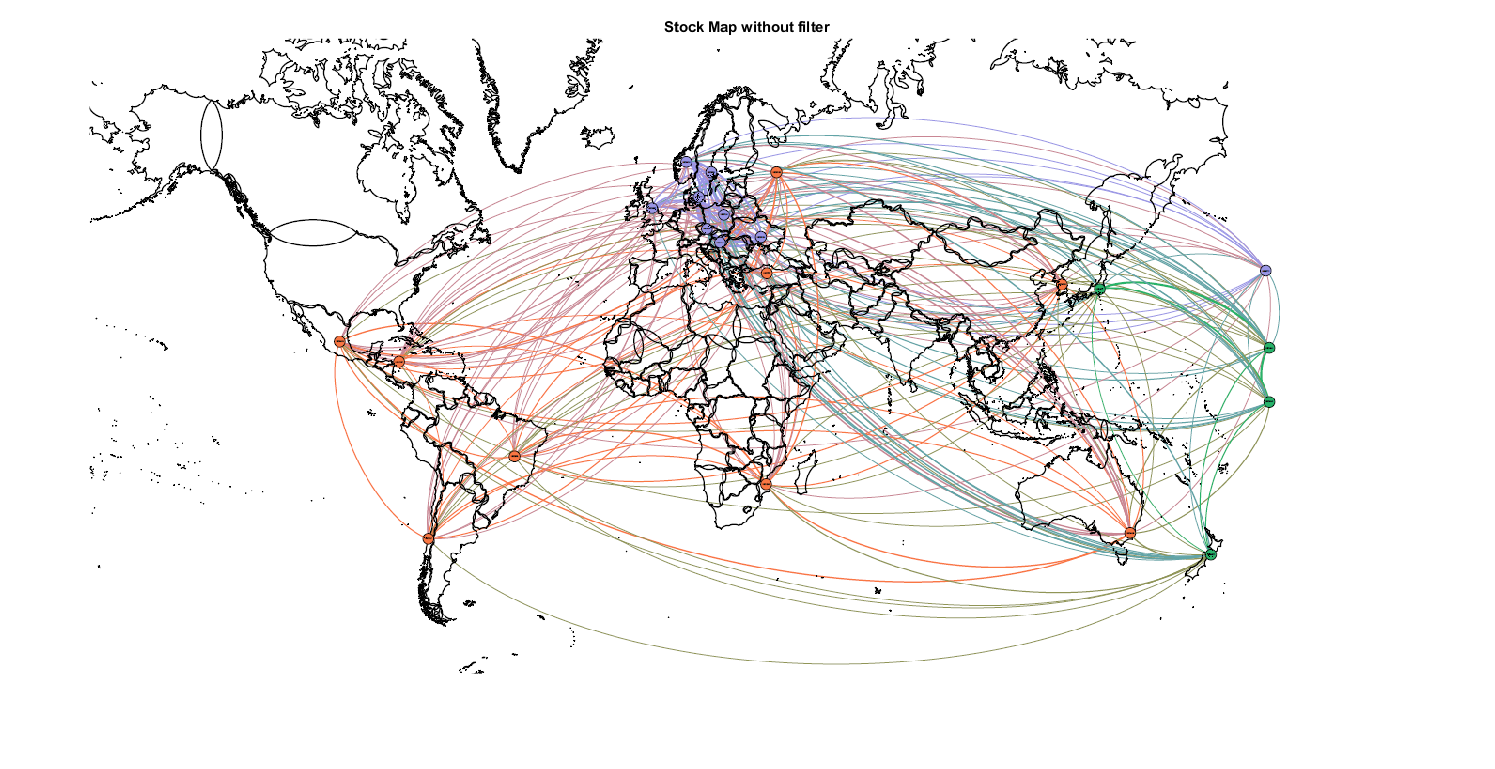

figure;
title("Stock Map without filter");
hold on;
imshow("map.png");
hold off;

Plot the currency World Map with insignificant edge is filtered ( high resolution image can be found in filter_1.pdf file ):

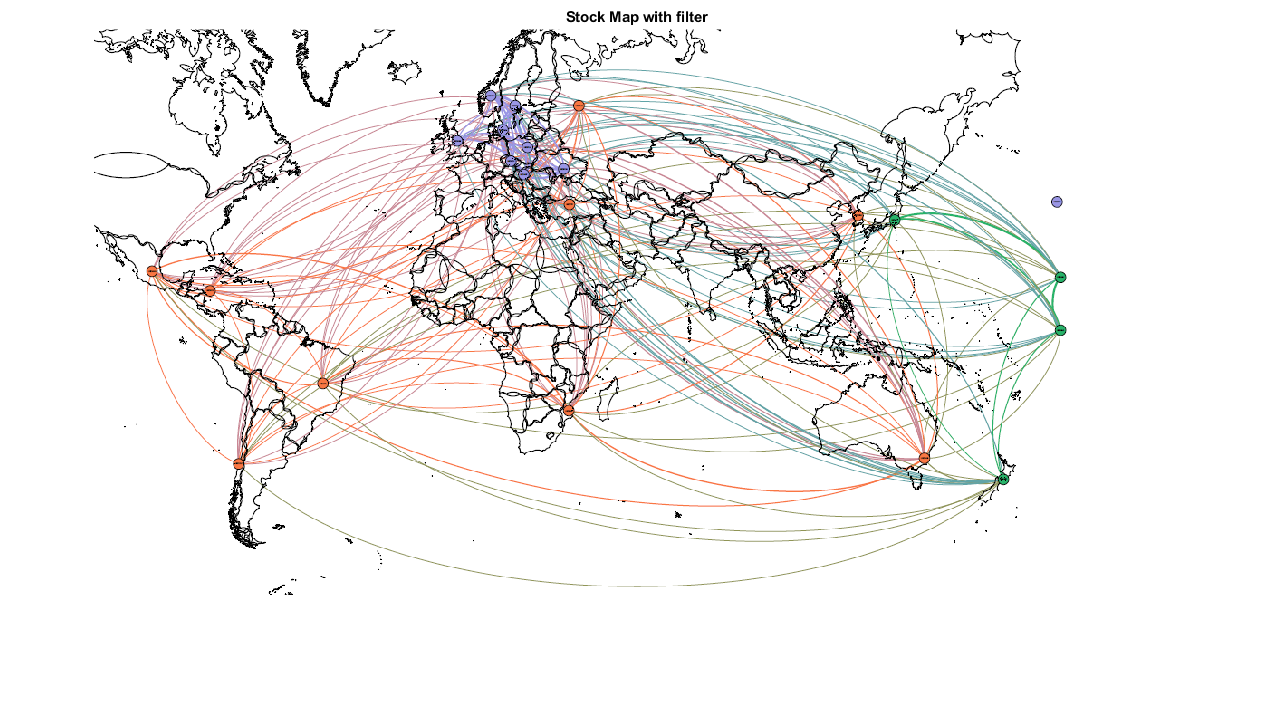

figure;
title("Stock Map with filter");
hold on;
imshow("map_filtered.png");
hold off;

**Question 8**: Based on the above, devise a new, computationally driven investment strategy for your firm. Explain the outlines of your strategy to your CEO in a one-page document that includes one image, along with an estimate of the % return your strategy would make yearly. You may wish to discuss the effect of over-fitting and/or keep some data for model fitting and some for validation.

The investment strategy would focus on eight European-based tickers: USDGBP, USDSEK, USDDKK, USDPLN, USDCZK, USDHUF, and USDRON. The analysis from Q5 shows that those tickers have a strong correlation to each other. Therefore, we would expect they will share a similar trend in next years. The outlined tickers are also considered the most traded currencies. As a result, the movement of their price is significant to yield profit. Investing in all eight currencies instead of one is a favorable strategy because it would increase the diversification of our investing plan. Diversification takes a role in managing risk and limiting the volatility of an asset's price movements. For example, if we only invest in one ticker, which unfortunately would have a subtle change in the next years, it would lead to unsuccessfully achieving financial goals.

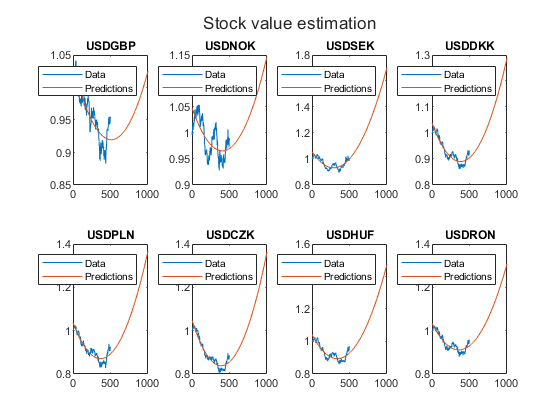

to_invest = ['USDGBP'; 'USDNOK'; 'USDSEK'; 'USDDKK'; 'USDPLN'; 'USDCZK'; 'USDHUF'; 'USDRON'];
to_invest = string(to_invest);

figure;
t = tiledlayout(2, 4);
title(t, "Stock value estimation");


year_to_predict = 2;
yearly_return = zeros(year_to_predict, length(to_invest));

for i = 1:length(to_invest)
    index = find(contains(string(tickers),to_invest(i)));
    y = data(:, index);
    X = (1:day)';
    X_ = (1:day + 252 * year_to_predict)';
    
    mdl = fitlm(X,y,'quadratic');
    ypred = predict(mdl,X_);
    
    ax1 = nexttile;
    plot(X,y,'-',X_,ypred,'-')
    title(ax1,  to_invest(i));
    legend(ax1, 'Data','Predictions')
    
    for j = 1:year_to_predict
        yearly_return(j, i) = (ypred(504 + 252 * j) - ypred(504 + 252 * (j - 1))) /  ypred(504 + 252 * (j - 1));  
    end    
end 

The estimation of value for the next two years is predicted by function fitlm provided by Matlab. It provides the linear regression model fit to the corrected prices data. Then we use that model to estimate the corrected price for the next two years. The results show that the model predicts a great increase in value for all of the 8 tickers. However, when constructing the model, overfitting is one of the problems that would be considered. It refers to the models that fit the training data too well. For example, suppose the dataset includes 100 data points, we can easily find the model that fits 100 points precisely by using a 99th-degree polynomial. However, when we applied this model to our test dataset, it would lead to a terrible fit. The cross-validation method is proposed to overcome this problem. This approach suggests dividing our dataset into two parts: one part is used to train the models and one part is used to see how well the models fit. The machine learning package could train millions of models from the training dataset and pick one that fits well on the test set. The below plot illustrates the expected yearly return for 8 investing tickers:

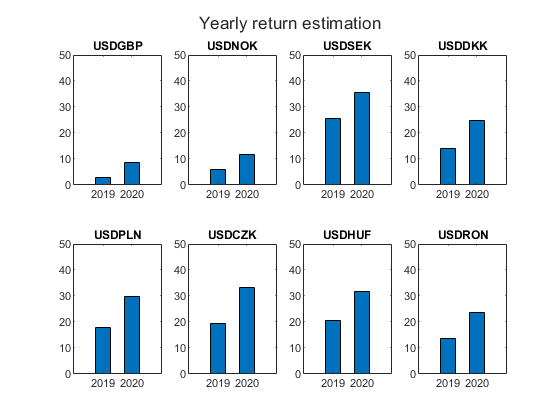

yearly_return_percent = yearly_return .* 100;
year = [2019, 2020];

figure;
t = tiledlayout(2, 4);
title(t, "Yearly return estimation");


for i = 1:length(to_invest)
    ax1 = nexttile;
    bar(year, yearly_return_percent(:, i), 0.5);
    title(ax1, to_invest(i));
    ylim([0 50]);     
end

The yearly return of all 8 tickers is predicted to increase over the next two years. The investment in USDSEK is expected to generate highest yearly return: around 25% and 35% for the years of 2019 and 2020 respectively. Meanwhile, the yearly return of USDGBP will be the lowest - only account for 2.7% and 8.5% in 2019 and 2020 respectively.

### Part II: Computational Complexity and OtherAreas of Module I

**Question 9: **“We are living in a period in human history in which new data is generated at such a rate and mis-analysed so badly that most of us can’t make sense of the world around us. This is similar to the 1500s when, following the invention of the printing press but before literacy was widespread, there followed perhaps the bloodiest period in human history”. Do you agree or disagree? Why or why not?

Before the invention of the printing press, producing a hand-copied book required a great amount of human effort, time, and cost. The printing press was invented by a German goldsmith, Johannes Guttenberg around 1436. In this period, the influence of the print press was not significantly represented since literacy was not sufficiently widespread. In other words, in the fourteenth century, the human already had a powerful "weapon" (the printing press), however, the materials were not widely available (low literacy rate). After a few decades, humans finally overcame that problem and successfully utilized the unlimited power of the print press. It assisted in the faster and wider dissemination of knowledge and information than ever before. The print press radically changed the consumption of news and made global news networks available to everyone. In addition, it forever changed the world by powers the Scientific Revolution. It was also considered as a very first factor in Industry Revolution in the eighteenth century. Last but not least, it contributed drastically to the development of Public Opinion and the Popular Revolution.

I partly agree that there have something in common between the problem we are confronting in the modern-day and that in the 1500s. The minor difference is that the materials, the large amount of data, are currently available for us. However, we still have not found a perfect tool to process them. 

Three popular methods are widely implemented to support Big Data Analytics ( BDA). Firstly, the most fundamental type of BDA approach is descriptive analytics. It utilized statistical techniques, such as mean, mode, median, variance, standard deviation, and distribution to summarize and describe useful patterns or correlations (Uthayasankar et al., 2017). However, the drawbacks of this method are it only reflects what has already happened and it greatly depends on the consistency of the instruments (Sarah et al., 2018).

Secondly, predictive analytics is also an important tool used to forecast and statistically model future possibilities (Uthayasankar et al., 2017). By analyzing current and historical data, it attempts to forecast the future. This approach is categorized into two groups: regression methods and machine learning methods. Nevertheless, there remain some significant drawbacks. The method involves some steps that could make the analysis more prescriptive than predictive. It is also difficult to apply in Human Resources issues. Besides, important variables are often missed out in the predictive models (Paramita, 2017).

Finally, prescriptive analytics is used to figure out the cause-and-effect relationship between analytic outcomes and business process optimization policies  (Uthayasankar et al., 2017). Company analysts may use prescriptive methods to make better decisions by identifying actions and examining their influence on business objectives, needs, and restrictions. There are not many examples of good prescriptive analytics due to the constraints on the number of dimensions that databases capture. Prescriptive solutions only offer partial insights into a complicated business problem.

All of the outlined methods have their own disadvantages which could lead to a serious misunderstanding of the data. In the future, what will happen if humans can devise an ideal approach to solve the Big Data analysis problem perfectly? Might we be able to predict the future possibilities exactly or solve millennium problems and change entire the laws of Physics just by analyzing experimental data? I agree that some huge changes to the world will occur as in the 1500s. However, I strongly disagree that it will be a factor contributing to the bloody war. It is just a tool and how it is utilized greatly depends on our humans.

**Question 10: **What is the computational complexity (in time) of your algorithm? Can you find a way to do any better? It’s thought that the permanent is computationally intractable – i.e. exponential time (in n) is required for its computation, a problem related to “P?=NP” in ways that we don’t yet understand. Why would the determinant be polynomial-time computable (it is, otherwise we couldn’t solve systems of linear equations or do pretty much anything useful with a computer), but the permanent, so similar in its definition, be intractable to compute?

The permanent algorithm using Ryser's formula:

% function p = permanent(A)
% %   Calculate the permanent of a square matrix A
% %   INPUT:
% %       A - square numeric matrix
% %   OUTPUT:
% %       The matrix permanent
% 
%     p = 0;
%     [n,m] = size(A);
%     
%     if(n~=m)
%         error('A must be square');
%     end   
%     
%     % loop over all 2^n submatricies of A
%     for i=1:(2^n - 1) %The last 2^n is no rows, skip that
%         % use bitget to index ever possible row-subset of A
%         indx = logical(bitget(i,(1:n))');        
%         p = p + ((-1)^(sum(indx))) * prod(sum(A(indx,:),1));
%     end    
%     p = p * (-1)^n;
%     
% end

The algorithm uses Ryser's formula to calculate the permanent of a square matrix A. The complexity of this algorithm is O( 2^(n-1) * n^2). It is shown that all currently available approaches for calculating the permanent take exponential time (Valiant, 1997). Even though there are similarities between the formula for the determinant and the permanent, the time complexity in calculating them is greatly different. Unlike the permanent, it only takes polynomial time to determine the determinant of a matrix. It is because we can use the LU-decomposition method (PA = LU) to calculate the determinant of a matrix A. We have det(A) is equal to the product of the diagonal elements of U, multiplied by ±1. Since the complexity of LU-decomposition is polynomial, the determinant is also polynomial-time computable.  In terms of the permanent problem, there is no known likewise method to solve it in polynomial time. There have been some methods that apply basic matrix transformation to see if it is possible to reduce the permanent to the determinant. However, they always generate negative outcomes. 

Solving the permanent problem in polynomial time complexity is related to the P versus NP problem. The problem questions if every problem which is quickly checkable can also be solved quickly. The sudoku game is one of the examples. It is widely known that it only requires polynomial time to verify the solution of the Sudoku grid. However, solving the grid requires exponential time complexity. It is stated the calculating permanents is #P-hard, even solving with (0, 1)-matrices is #P-complete. Calculating the permanent or solving Sudoku game in polynomial time complexity would imply P = NP.  It means that if anyone could propose a polynomial-time solution for the permanent solution, it will also give a polynomial-time solution to any NP problem. According to Gasarch, his polls conducted in 2019 indicate 99 percent of researchers believe that P ≠ NP. He also stated: ″This does not bring us any closer to solving P=?NP or to know when it will be solved, but it attempts to be an objective report on the subjective opinion of this era.″ If P = NP is proved, it will definitely exert an enormous impact on the modern computer science. For example, we can find a faster way for protein folding problems that would help us cure cancer.

### References

- Thales Marques, (2020). **An Empirical view of Marchenko-Pastur Theorem. **Retrieved from: [https://medium.com/swlh/an-empirical-view-of-marchenko-pastur-theorem-1f564af5603d](https://medium.com/swlh/an-empirical-view-of-marchenko-pastur-theorem-1f564af5603d)

- Newman, Mark EJ, (2004). **Fast algorithm for detecting community structure in networks**. Physical review E 69.6.

- Dave Roos, (2019). **7 Ways the Printing Press Changed the World. **Retrieved from: [https://www.history.com/news/printing-press-renaissance](https://www.history.com/news/printing-press-renaissance)

- Sarah E. Kemp, May Ng, Tracey Hollowood, Joanne Hort, (2018). **Introduction to Descriptive Analysis. **Descriptive Analysis in Sensory Evaluation, 1.

- Paramita (Guha) Ghosh, (2017). **Limitations of Predictive Analytics. **Retrieved from: [https://www.dataversity.net/limitations-predictive-analytics-lessons-data-scientists/](https://www.dataversity.net/limitations-predictive-analytics-lessons-data-scientists/)

- Sivarajah, Uthayasankar & Kamal, Muhammad & Irani, Zahir & Weerakkody, Vishanth. (2016). **Critical analysis of Big Data challenges and analytical methods**. Journal of Business Research. 70. 10.

- Valiant, Leslie G, (1979). **The complexity of computing the permanent**. Theoretical Computer Science, Elsevier, 8 (2): 189–201.

- John D. Cook, (2015). **A subtle way to over-fit. **Retrieved from: [https://www.johndcook.com/blog/2015/03/17/a-subtle-way-to-over-fit/](https://www.johndcook.com/blog/2015/03/17/a-subtle-way-to-over-fit/)

- Trading View, (n, d). **Most traded currency**. Retrieved from: [https://www.tradingview.com/ideas/eur-euro/](https://www.tradingview.com/ideas/eur-euro/)

- William I. Gasarch, (2020). **The third P=?NP Poll1**. SIGACT News. 33 (2): 34–47.

[](https://onlinelibrary.wiley.com/action/doSearch?ContribAuthorStored=Kemp%2C+Sarah+E)